clear all 
clc

Загружаем данные из фала

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t1", "v1", "t2", "v2"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Miror = readtable("зеркало.txt", opts);
TestMom = readtable("5мнТест.txt", opts);
Scan  = readtable("скан.txt", opts);
Stand = readtable("стенд.txt", opts);
%% Clear temporary variables
clear opts

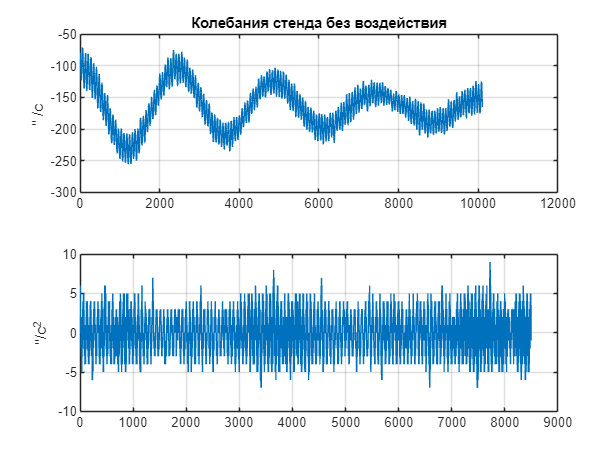

i = 8500;

TestMomMean = (TestMom.v2(400:i+399))+168;
MirorMean = (Miror.v2(800:i+799))+150;
ScanMean = (Scan.v2(500:i+499))+165;
StadMean = (Stand.v2);


stadSmooth = smooth(StadMean, 0.1, 'loess');
stadSmoothA = diff(stadSmooth);
StadMeanA = diff(ScanMean);
figure
subplot(2,1,1)
plot(StadMean);
title("Колебания стенда без воздействия")
ylabel("'' /c ")
grid on
subplot(2,1,2)
plot(StadMeanA)
ylabel("''/c^2")
grid on

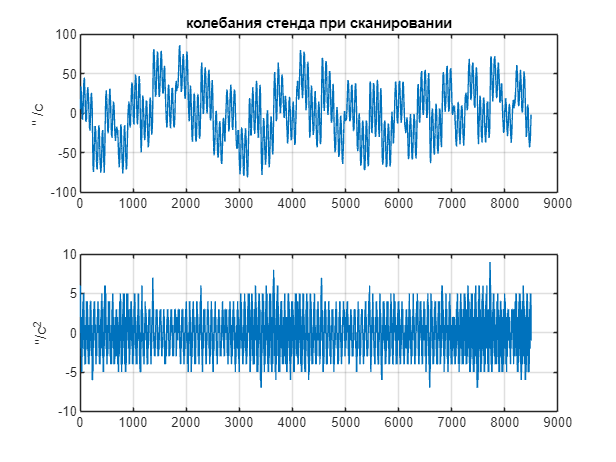

figure
subplot(2,1,1)
plot(ScanMean)
ylabel("'' /c ")
title("колебания стенда при сканировании")
grid on
subplot(2,1,2)

plot(diff(ScanMean))
ylabel("''/c^2")
grid on

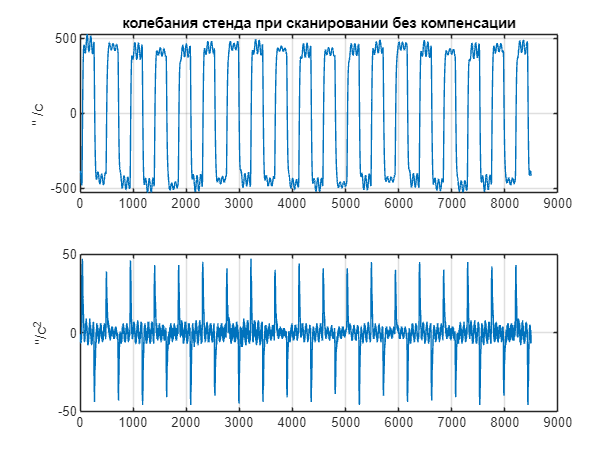

figure
subplot(2,1,1)
plot(MirorMean)
ylabel("'' /c ")
title("колебания стенда при сканировании без компенсации")
grid on
subplot(2,1,2)

plot(diff(MirorMean))
ylabel("''/c^2")
grid on

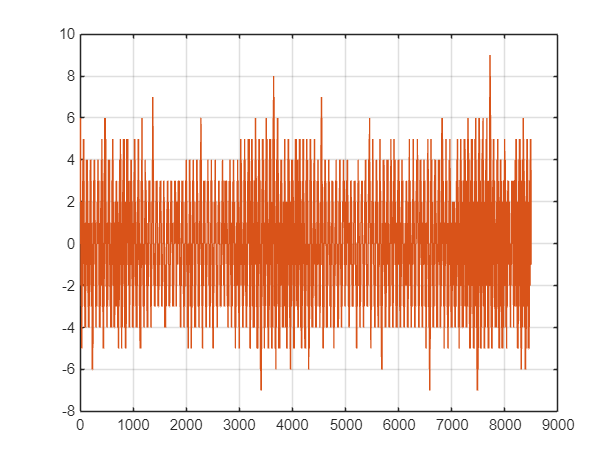



figure
plot(diff(ScanMean));
grid on
hold on
plot(StadMeanA)
hold off







t = 0:0.01:10000;
figure
%plot(t(1:i),TestMomMean, "green");

%p1 = plot(t(1:i), MirorMean(1:i));
grid on
hold on
p2 = plot(t(1:i), ScanMean(1:i));
xlabel("Время,с")
ylabel("\omega ''/c")
title("Скорость колебаний подвеса");
nt = 4.57

nt = 4.5700

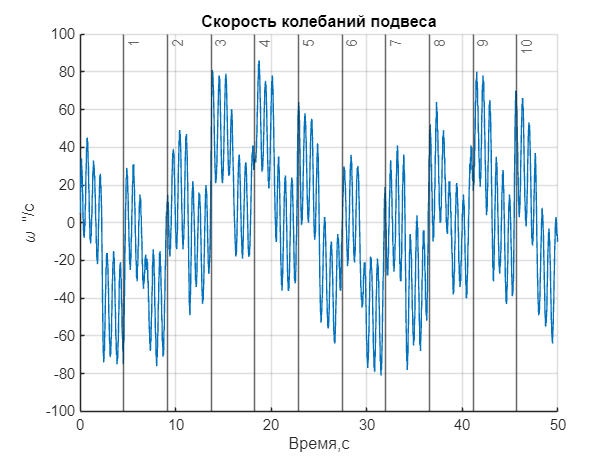

for i = 1:10
    xline(i*nt, '-', {i});
end
%legend([p1 p2], {'Зеркало без маховка', 'зеркало с маховиком'}, "Location","southeast")
hold off
xlim([0 50])

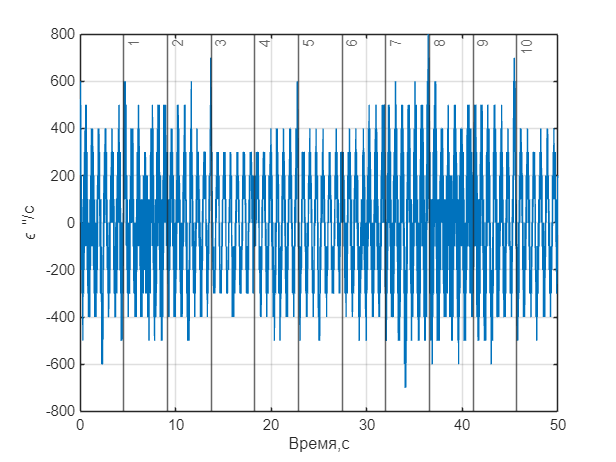



ScanMeanA = diff(ScanMean)/0.01;

figure
plot(t(1:length(ScanMeanA)), ScanMeanA);
grid on
for i = 1:10
    xline(i*nt, '-', {i});
end
xlim([0 50])
xlabel("Время,с")
ylabel("\epsilon ''/c")

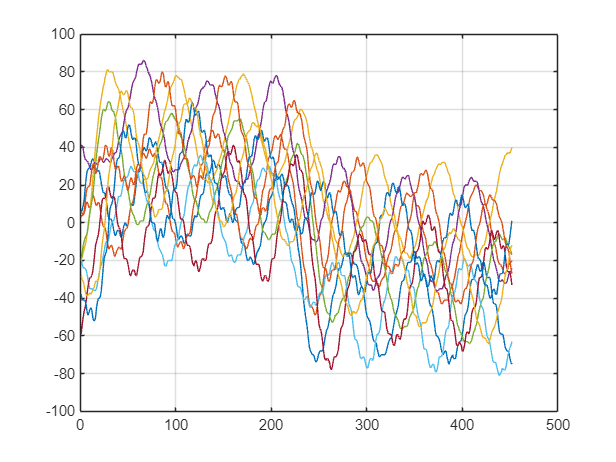



nt = 452;
mt = zeros(nt,10);
mt(:,1) = ScanMean(1 : nt);
%mt(:,1) = mt(:,1) + 124;
for i = 2 : 10
    mt(:,i) = ScanMean(i*nt :i*nt+nt-1);
  %  mt(:,i) = mt(:,i) + abs(mt(1,i));
end

plot(mt(:,:))
 grid on

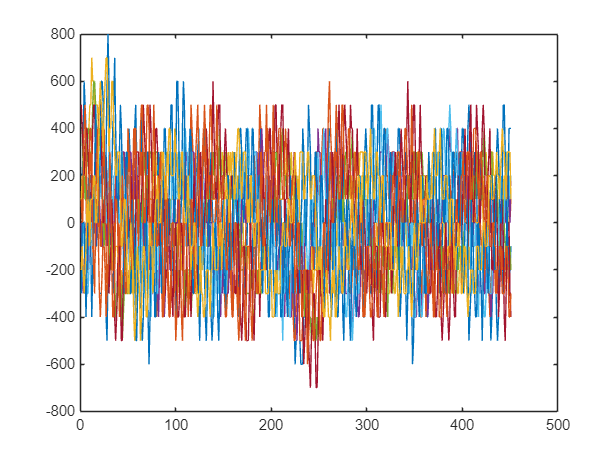


dmt = diff(mt)/0.01;

plot(dmt)




max_d_mt = max(dmt)

max_d_mt =    600   600   700   400   600   500   600   800   500   700


max_d_mt1 = [600 600 700 300 600 400 500 800 600 700]

max_d_mt1 =    600   600   700   300   600   400   500   800   600   700


Математическое ожидание $\overset{-}{х} =\frac{1}{N}\bullet \sum_{i=1}^N x_i$

Mean_max_d_mt = mean(max_d_mt)

Mean_max_d_mt = 600

Дисперсия 

Var_max_d_mt = var(max_d_mt)

Var_max_d_mt = 1.3333e+04

СКО

Std_max_d_mt = std(max_d_mt)

Std_max_d_mt = 115.4701

CКО среденго арифметического

Std_max_d_mt_mean = Std_max_d_mt/sqrt(length(max_d_mt))

Std_max_d_mt_mean = 36.5148

Погрешность измерения ${\Delta x\;=\;S}_{\overset{-}{x} } +t$, t - коэффициент стьюдента 

t = 2.626 для 10 измерений

student_koeff = 2.626;
err_d_mt = Std_max_d_mt_mean*student_koeff

err_d_mt = 95.8880

итоговая погрешность

x = $\overset{-}{x} \pm \Delta x=7\ldotp 4\pm 1\ldotp 050$

Обработка измерений зеркала без маховика

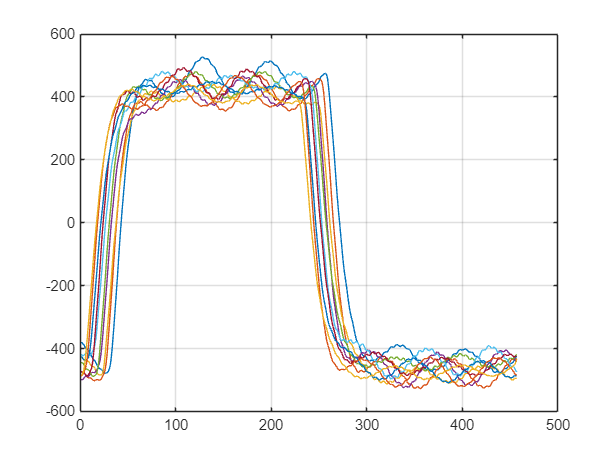

nt = 457;
mz = zeros(nt,10);
mz(:,1) = MirorMean(1 : nt);
%mt(:,1) = mt(:,1) + 124;
for i = 2 : 10
    mz(:,i) = MirorMean(i*nt :i*nt+nt-1);
  %  mt(:,i) = mt(:,i) + abs(mt(1,i));
end

plot(mz(:,:))
grid on

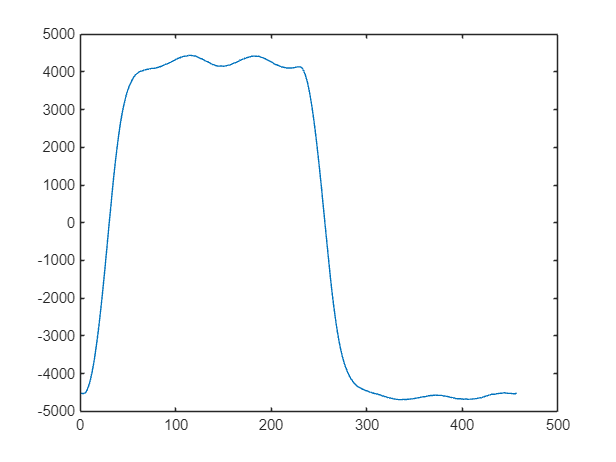

%Производная момента зеркала
dmz = diff(mz);
sum_dmz = sum(dmz,2);
sum_mz = sum(mz, 2);
figure
plot(sum_mz)

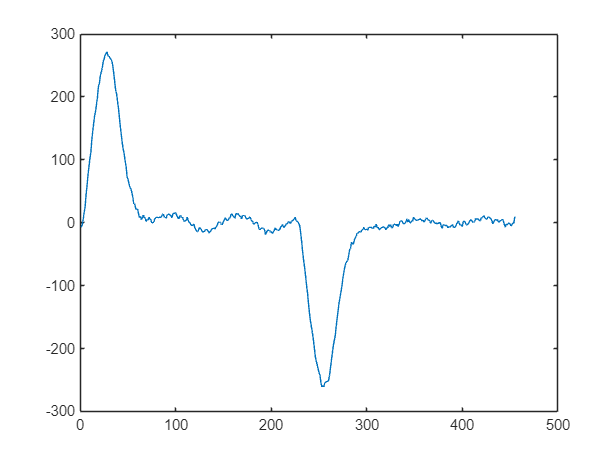

figure
plot(diff(sum_mz))

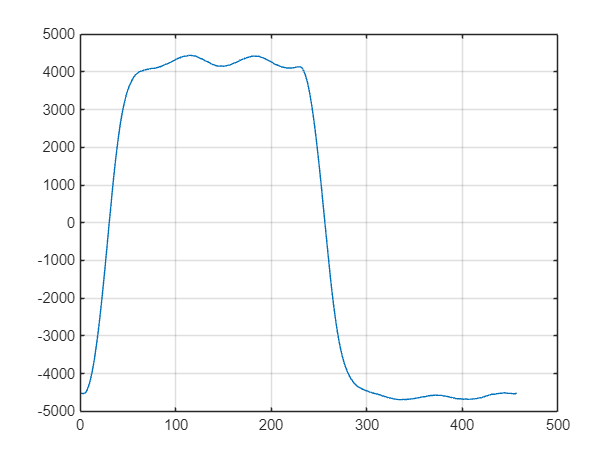



figure
plot(sum_mz(:,:))
grid on

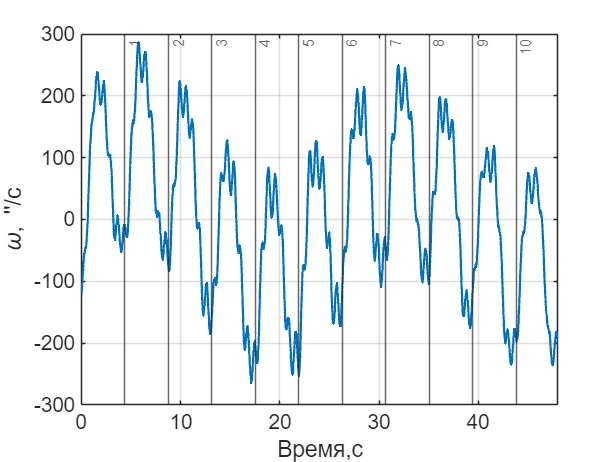


figure()
p1 = plot(t(1:length(TestMomMean)), TestMomMean, "LineWidth",1.5);
grid on
hold on

xlabel("Время,с", "FontSize",14)
ylabel("\omega, ''/c", "FontSize",14)
set(gca, 'FontSize', 14)   % задаёт размер шрифта для делений на осях
nt = 4.38;
for i = 1:10
    xline(i*nt, '-', {i});
end
xlim([0 48])
hold off
print(gcf, '../img/test-gyro.png', '-dpng', '-r600')


TestMomA = diff(TestMomMean)/0.01;
figure
plot(t(1:length(TestMomA)), TestMomA)
nt = 4.38

nt = 4.3800

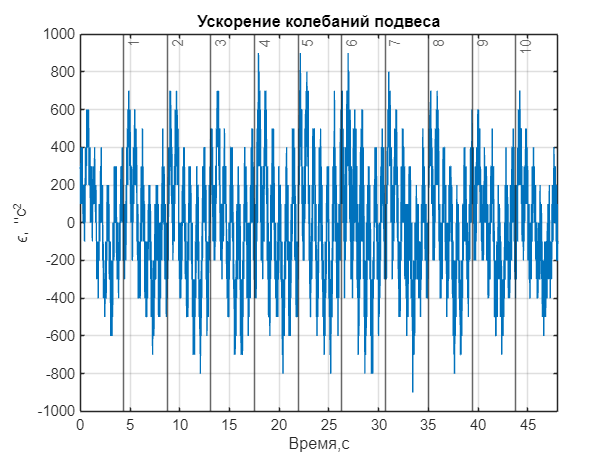

for i = 1:10
    xline(i*nt, '-', {i});
end
xlabel("Время,с")
ylabel("\epsilon, ''c^2")
title("Ускорение колебаний подвеса")
xlim([0 48])
grid on

Обработка измерений тестового воздействия

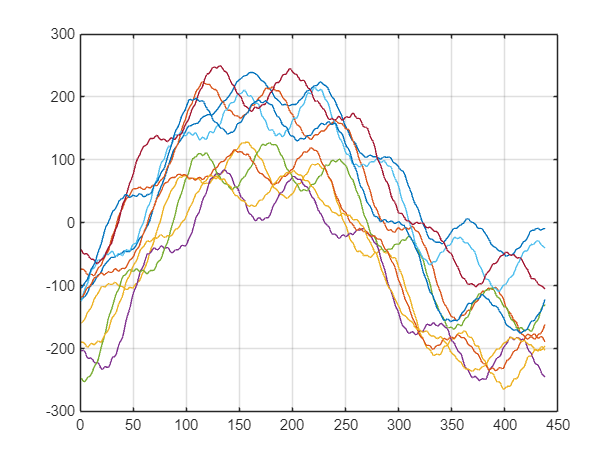

nt = 438;
mt = zeros(nt,10);
mt(:,1) = TestMomMean(1 : nt);
%mt(:,1) = mt(:,1) + 124;
for i = 2 : 10
    mt(:,i) = TestMomMean(i*nt :i*nt+nt-1);
  %  mt(:,i) = mt(:,i) + abs(mt(1,i));
end

plot(mt(:,:))
 grid on

 
 

%Производная тестового момента
dmt = diff(mt(:,:))/0.01;
max_d_mt = max(dmt)

max_d_mt =    600   700   700   900   900   900   800   700   600   700


Математическое ожидание $\overset{-}{х} =\frac{1}{N}\bullet \sum_{i=1}^N x_i$

Mean_max_d_mt = mean(max_d_mt)

Mean_max_d_mt = 750

Дисперсия 

Var_max_d_mt = var(max_d_mt)

Var_max_d_mt = 1.3889e+04

СКО

Std_max_d_mt = std(max_d_mt)

Std_max_d_mt = 117.8511

CКО среденго арифметического

Std_max_d_mt_mean = Std_max_d_mt/sqrt(length(max_d_mt))

Std_max_d_mt_mean = 37.2678

Погрешность измерения ${\Delta x\;=\;S}_{\overset{-}{x} } +t$, t - коэффициент стьюдента 

t = 2.626 для 10 измерений

student_koeff = 2.626;
err_d_mt = Std_max_d_mt_mean*student_koeff

err_d_mt = 97.8652

итоговая погрешность

x = $\overset{-}{x} \pm \Delta x=7\ldotp 4\pm 1\ldotp 050$

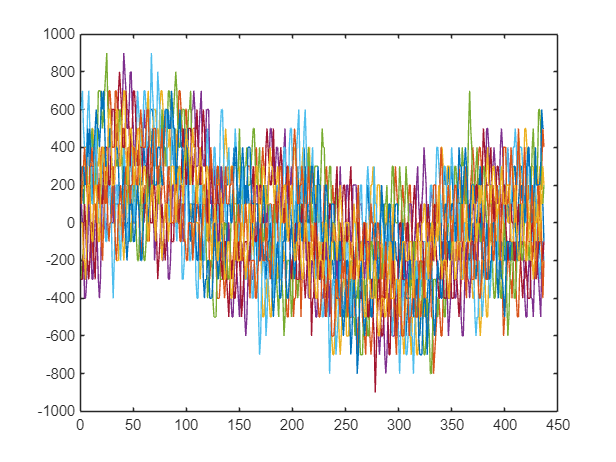



sum_dt = sum(dmt,2);
sum_mt = sum(mt, 2);
figure
plot(dmt(:,:))

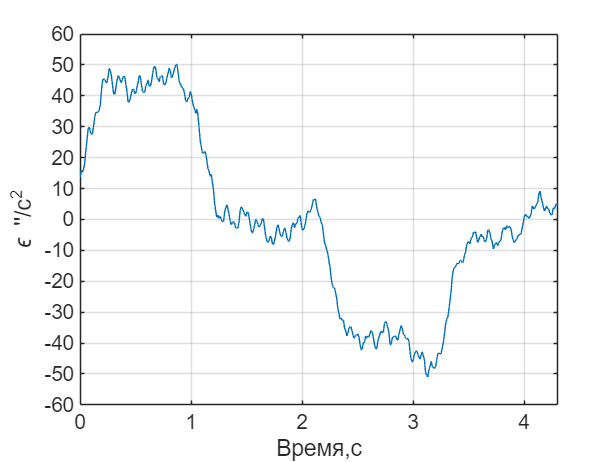

figure
t =t';
a = smooth(diff(sum_mt));
plot(t(1:length(sum_mt)-1), a*1.7)
grid on
hold on
xlim([0,4.3])
xlabel("Время,с", "FontSize",14)
ylabel("\epsilon ''/c^2", "FontSize",14)
yticks(-60:10:60)
set(gca, 'FontSize', 14)   % задаёт размер шрифта для делений на осях
print(gcf, '../img/test-gyro-acc.png', '-dpng', '-r600')

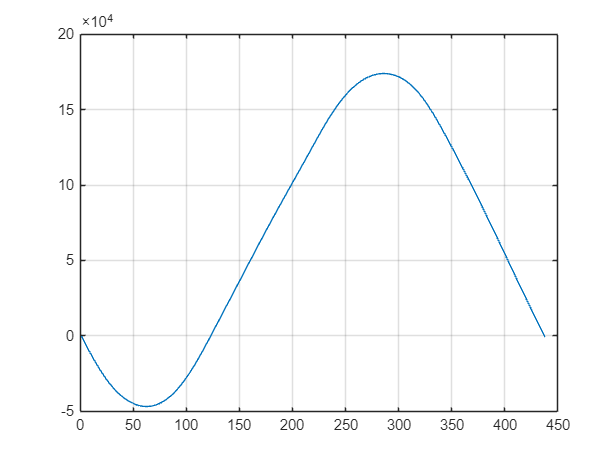

test = cumtrapz(sum_mt);


figure
plot(test(:,:))
grid on

Вычислим производную как разность сосуыдних отсчетов деленные на шащ времен t = 0.01c

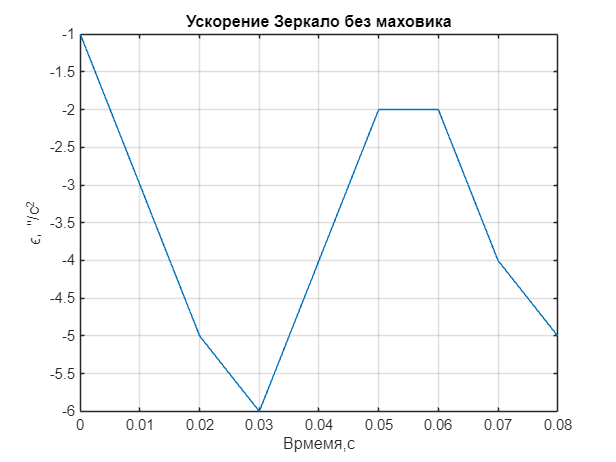

TestMomAcc = diff(TestMomMean(1:i));
MirorAcc = diff(MirorMean(1:i));
ScanAcc = diff(ScanMean(1:i));

figure
plot(t(1:length(MirorAcc)), MirorAcc);
grid on
xlabel("Врмемя,с");
ylabel("\epsilon, ''/c^2");
title("Ускорение Зеркало без маховика");

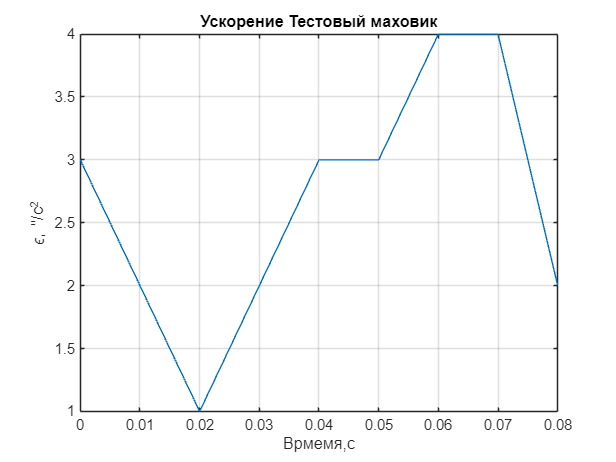


figure
plot(t(1:length(TestMomAcc)),TestMomAcc);
grid on
title("Ускорение Тестовый маховик");
xlabel("Врмемя,с");
ylabel("\epsilon, ''/c^2");

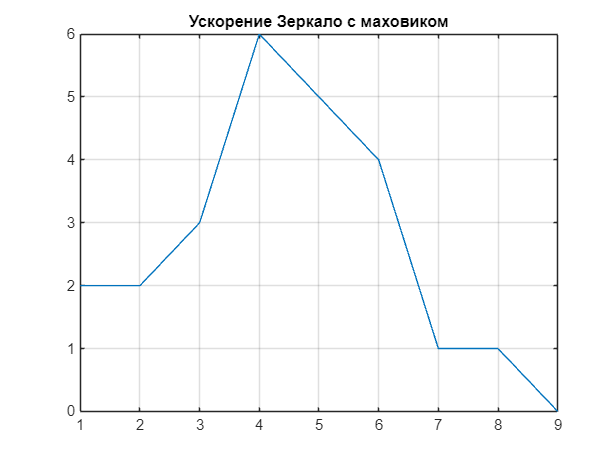

figure
plot(ScanAcc);
grid on
title("Ускорение Зеркало с маховиком");

Усреднение по 17-ти измерениям.

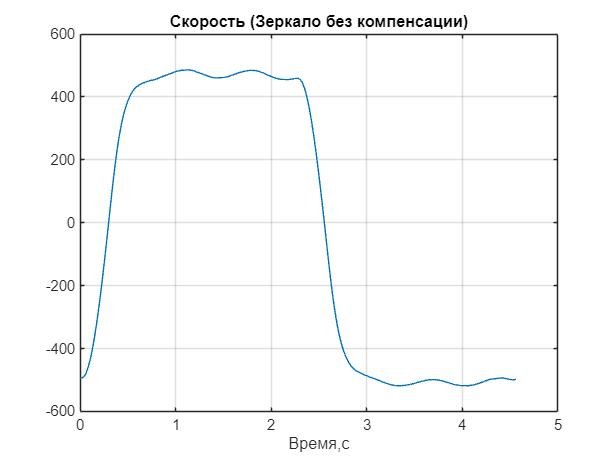

nm = 457; % число отсчетов в одном периоде
sumMirror = MirorMean(1:nm);
for i = 1:10
    sumMirror = sumMirror+MirorMean((nm*i)+1 : nm*(i+1));
end
plot(t(1:length(sumMirror)), sumMirror/10);
xlabel('Время,с');
title("Скорость (Зеркало без компенсации)")
grid on

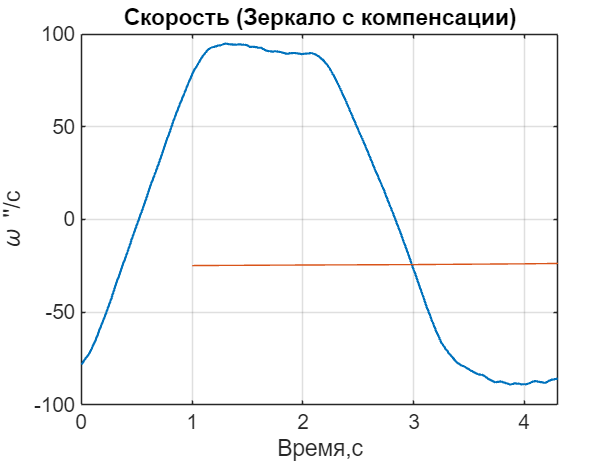

nt = 439 ;
sumTest = TestMomMean(1:nt);
for i = 1:10
    sumTest = sumTest + TestMomMean((nt*i)+1 : nt*(i+1));
end
plot(t(1:length(sumTest)),sumTest/17, "LineWidth",1.5)
title("Скорость (Тестовое воздействие)")
grid on
grid on
hold on
xlim([0,4.3])
xlabel("Время,с", "FontSize",14)
ylabel("\omega ''/c", "FontSize",14)
set(gca, 'FontSize', 14)   % задаёт размер шрифта для делений на осях

ns = 449;
sumScan = ScanMean(1:ns);
for i = 1:17
    sumScan = sumScan+ScanMean((ns*i)+1 : ns*(i+1));
end

plot(sumScan/17)
title("Скорость (Зеркало с компенсации)")
grid on

dt = 1;

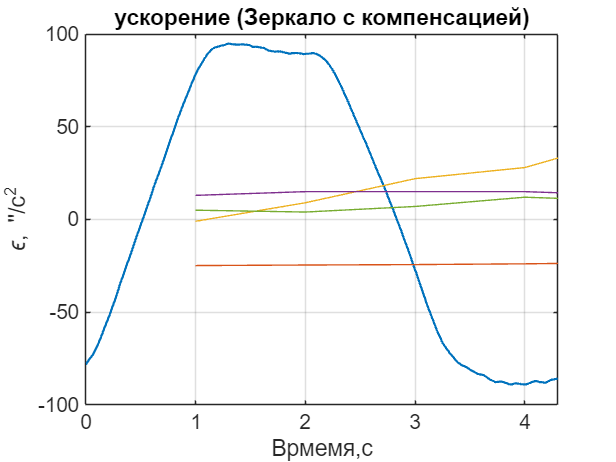

Macc = diff(sumMirror)./dt;
Tacc = diff(sumTest)./dt;
Sacc = diff(sumScan)./dt;


plot(Macc);
grid on
xlabel("Врмемя,с");
ylabel("\epsilon, ''/c^2");

plot(Tacc);
title("ускорение (Тестовое вздействие)")

grid on

plot(Sacc);
grid on
title("ускорение (Зеркало с компенсацией)")